## Using State-Space Analysis

**x_dot = Ax + Bu**

Definitions of the following

x_dot : various state parameters (position, velocity, angle, angular velocity)

A : Matrix for system of equations or dynamics (tells you how different variables interact)

B: Actuation input matrix (pre-defined, parameters we can control and their limitations)

x: State of the system

u: Control variable (control law implementation)

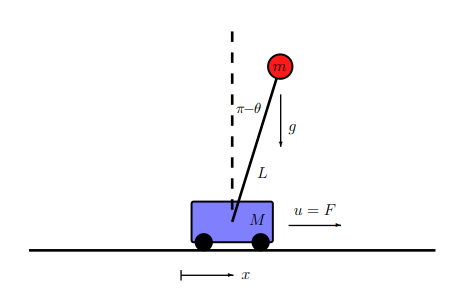

Nonlinear Dynamics derived using Lagrange 

x = cart position

x_dot = −m2L 2 g cos(θ) sin(θ) + mL2 (mLω2 sin(θ) − δv) + mL2u mL2 (M + m(1 − cos(θ) 2 )) (8.67b) 

θ = pendulum angle

θ_dot = (m + M)mgL sin(θ) − mL cos(θ)(mLω2 sin(θ) − δv) + mL cos(θ)u mL2 (M + m(1 − cos(θ) 2 ))

## Linearize the system about a fixed point using the Jacobian to find the A and B matrix.

The Jacobian is a matrix of partial derivatives , if we look at very small increments at small time samples, the relationship is pretty much linear.

We let x1 = x , x2 = x_dot, x3 = θ. x4  = θ_dot

We are linearizing about the point θ = 0/π (the cart down and up position)

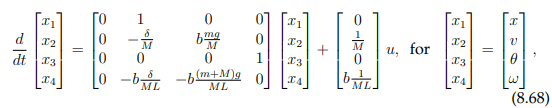

clear all, close all, clc

m = 1; %pendulum mass
M = 5; %cart mass
L = 2; %distance from cart to pendulum
g = -10; %gravitational force
d = 1; %damping

b = 1; %pendulum Orientation

%Define A and B Matrix from the Jacobian

A = [0 1 0 0;
    0 -d/M -b*m*g/M 0; %changed to -b*m*g/M and it worked 
    0 0 0 1;
    0 -b*d/(M*L) -b*(m+M)*g/(M*L) 0];

B = [0; 1/M; 0; b*1/(M*L)];

Checking if the System is Controllable

Is the system Controllable?

The controllability matrix

For the system to be controllable, its rank must equal the amount of columns it spans. For our system, we have 4 inputs we will be trying to control so the rank must be equal to 4 and the determinant should be non-zero. We want to make sure that our actuation has the ability to manipulate all inputs and that A & B are coupled together.

ctrb(A,B); %creates the controllability matrix
rank(ctrb(A,B)); %outputs the rank of the controllability matrix
det(ctrb(A,B)); %outputs the determinant of the controllability matrix (should be non-zero)

Pole Placement

Now that our system is known to be controllable we now develop a control law based on placement of eigen values. We are able to modify (A-BK), specifically K which is a matrix used to stabilize the non-linear system. Remember that we want the real part of the eigen values to land on the LHP if we graph Real-axis vs. Imaginary-axis. The further from zero-point will correlate with a more aggressive yet stable controller. 

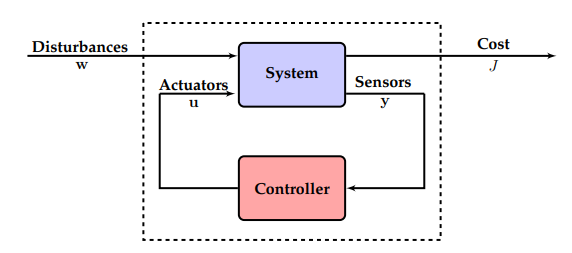

We can place our poles manually, by first specifying the eigen values we want for the closed loop controller,

Then we use the MATLAB place function to automatically find the gain matrix K to give us these eigenvalues in a closed-loop feedback system.

We can check our eigen values using MATLAB eig function

eigs = [-1; -1.1; -1.2; -1.3]; %Specifiying eigen values we want
K = place(A,B,eigs); %Built in matlab function to find K matrix for specified eigen values
eig(A-B*K); %eigen values of closed loop feedback system

Of course placing the poles as far as possible makes a very fast system, however, we are limited by actuation ability. We also risk the system breaking and becoming unstable. A faster system is actually less robust, i.e. the non-linear system will not act like the linear system we created. This is why we need to optimize where these poles area.

Linear Quadratic Regulator (LQR)

Where are the best eigen values? There are so many combinations in terms of where we can place these poles.

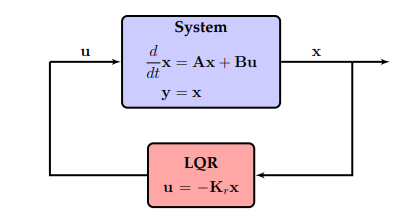

If our system is controllable, there exists an ideal spot where we can place our poles based on a cost function that includes both system speed and actuation. It needs to consider both and we can choose the weights of these.

Matrix Q tells us how bad of a penalty it is if x is not where its not supposed to be

Value R is the cost of actuation (how much energy does it take?) High values means actuation is expensive while lower values close to zero means its cheap. 

Our goal is to minimize the cost function using a linear controller

In MATLAB using lqr function will give the optimal k matrix given the matrix Q and R 

Q = [1 0 0 0; %x
    0 1 0 0 ; %x_dot
    0 0 10 0; %theta
    0 0 0 100]; %theta_dot

R = 0.0001; %CHANGED
K = lqr(A,B,Q,R);

We can look into the pole placement by looking into the eigenvalues of the new K

%eigs(A-B*K);

Full State Estimation

Sometimes, we don't have access to all the measurements of the full-state. Sensors are expensive, and putting them on everything is just not feasible sometimes. The K matrix represents the optimal full-state feedback controller which we can grab quickly.

However, is it possible that we can have only measurement of some variables in the system and estimate the true state of other variables to get an estimate of the full-state?

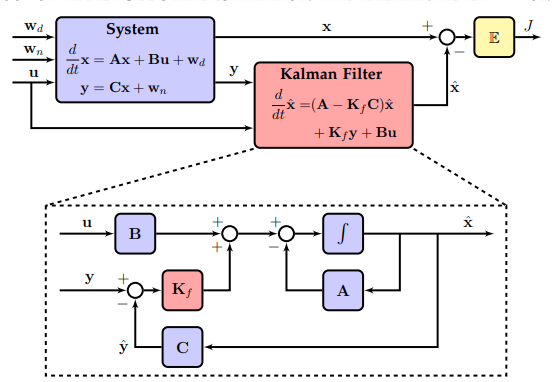

Is The System Observable?

We can use measurements of different variables but need to check if that allows the system to be observable. It answers the question, if we look into variable ___, can we estimate the rest of the system?

To be observable, the rank of the system must equate the number of rows, or must span all its rows. In this case, the rank must equal 4.

For my system, we can measure the position of the cart using the wheel circumference and encoder readings, we can measure the theta and theta dot angles from using the filtered acc/gyro. This has a rank of 4.

C = [1 0 0 0]; %Rank = 4
%C = [0 1 0 0]; %Rank = 3
%C = [0 0 1 0]; %Rank = 3
%C = [0 0 0 1]; %Rank = 3
%C = [1 0 1 1]; %Rank = 4 //Our System we can have everything
obsv(A,C);
rank(obsv(A,C));

Building A Kalman Filter

The Kalman is a state estimator, it has the model of the system to be able to estimate the state values, however, it also takes in measurement values. The Kalman filter will weight the disturbances (Wd) which effect the systems model and the noise (Wn) which will effect the sensor measurements and weight them against one another to decide when to favour the system model estimate or the sensor value.

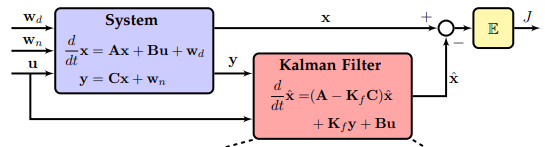

To build the Kalman Filter, we need to create an augmented(amplified) system that includes disturbances and noise. The Kalman filter will build an estimate of the full system (x_hat).

Disturbance (Vd) covariance is a disturbance that effects the measured inputs (i.e. large kicks to the system)

Noise covariance (Vn) represents the sensor noise which is just a scalar value.

The ratio of Vd:Vn tells us how the filter balances its model of the system from its measurements y

D = zeros(size(C,1), size(B,2)); %Feed through term required

Vd = 0.001*eye(4); %Matrix of Disturbance co-variance
Vn = 0.001; %Noise co-variance


MATLABs lqe function essentially finds the optimal Kf gains given covariance for disturbances and noise

%Builds the Kalman Filter
[L,P,E] = lqe(A,Vd,C,Vd,Vn);
Kf = (lqr(A',C',Vd,Vn))';

We can investigate what is happening when we are creating the Kalman Filter. The code below displays distrubances and noise being considered when creating the Kalman Filter as well as graphing against the real system dynamics given an impulse at two given time frames.

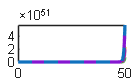

B_aug = [B Vd 0*B];
D_aug = [0 0 0 0 0 1];
sysC = ss(A, B_aug,C,D_aug);
sysTrue = ss(A,B_aug,eye(4),zeros(4,size(B_aug,2))); %Defining State Space for True System
sysKF = ss(A-Kf*C, [B Kf], eye(4), 0*[B Kf]); %Defining State space for Kalman Filtered System


%Graphing what we see
dt = .01;
t = dt:dt:50;

%Creating Disturbances
uDist = sqrt(Vd)*randn(4,size(t,2));
uNoise = sqrt(Vn)*randn(size(t));

u = 0*t;
u(1/dt) = 20/dt;
u(15/dt) = -20/dt;

u_aug = [u; uDist; uNoise]; %Inputs with Disturbance and Noise
[y,t] = lsim(sysC,u_aug,t); % noisy measurement
[xtrue,t] = lsim(sysTrue,u_aug,t); % true state
[xhat,t] = lsim(sysKF,[u; y'],t); % state estimate

plot(t,xtrue,'-',t,xhat,'--','LineWidth',2);

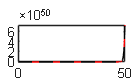

figure
plot(t,y)
hold on
plot(t,xtrue(:,1),'r')
plot(t,xtrue(:,1),'k--')

We are looking at the position of the cart estimate after being given two impulses. When we investigate the pendulum up position (b = -1) we can see the effects of the Kalman Filter. The blue signal shows the generated noise and the red marks the Kalman Filter estimate that bypasses the noise and disturbances. 

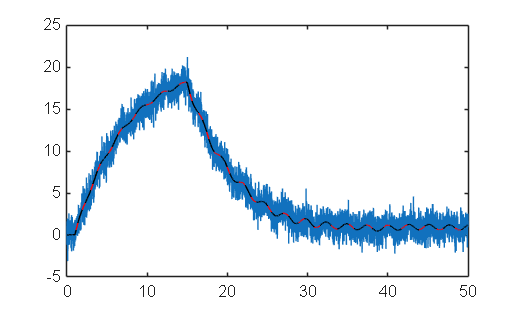

We can also investigate the rest of the variables, The figure below displays the dashed lines with the estimated values and the solid lines are the true values versus the dashed estimates. They perfectly line up matching the dynamical system.

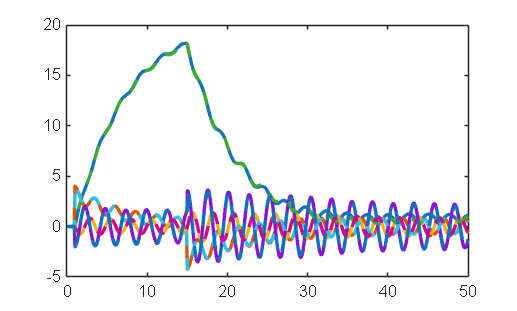

Linear Quadratic Gaussian (LQG)

When we combine a Kalman Filter and LQR, we can create a LQG controller.

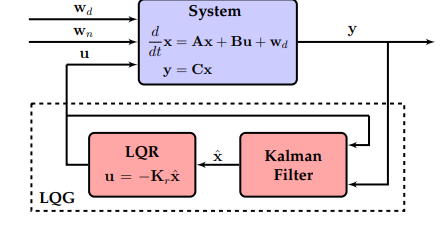

The separation principle shows us that the LQR and LQE (Kalman Filter) poles remain stabilized when combining both together. They can be designed separately and be combined to still have the same poles.

When we combine the full-state estimate from the Kalman Filter (x_hat) and LQR 

We can see that the diagonal terms 

## Simulink Implementation

Implementation into MATLAB exclusively is rather difficult just using equations alone. Instead we can use Simulink for simulation.

LQR Implementation

This involves us having the four states being measurable (i.e. sensors for position, velocity, angle, and angular velocity)

We use this feature called the S-Function Builder that takes in C Code and transfers it to a simulink model that can take inputs and have outputs.

First we build this S-Function to represent our pendulum cart system using a s-function builder block.

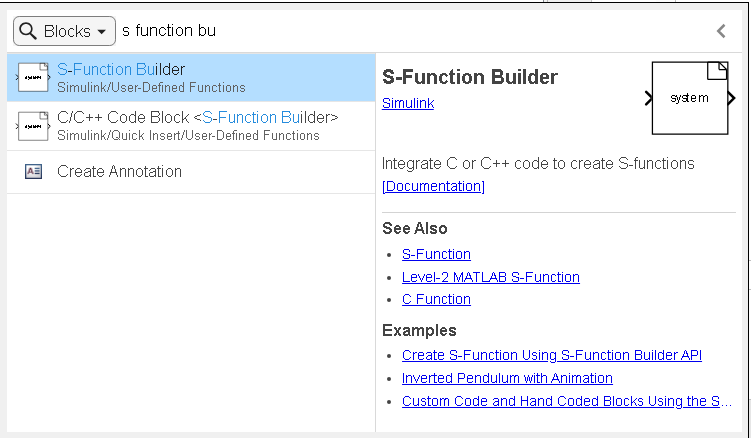

We have the non-linear dynamic equations and we implement those into a simulink s-model.

We change the settings to track the number of available states to 4 as we we are looking at 4 variables. 

We change the  inital conditions (Continuous states IC) to represent where the cart begins. Pi indicates that it is the pendulum up position

Sample mode is Continuous

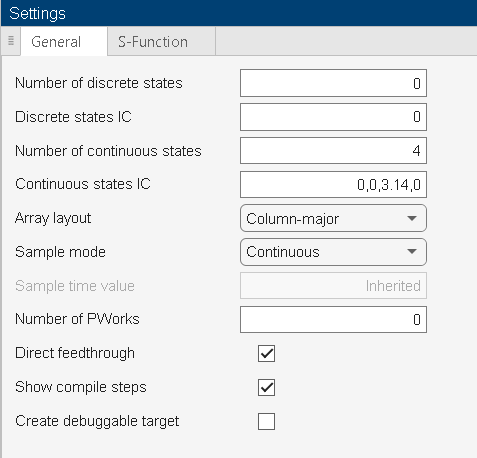

The s-function building block

%{
/* Includes_BEGIN */
#include <math.h>
/* Includes_END */

/* Externs_BEGIN */
/* extern double func(double a); */
/* Externs_END */

void cartpendulum_system_Start_wrapper(real_T *xC)
{
    /* Start_BEGIN */
    /*
    * Custom Start code goes here.
    */
    /* Start_END */
    }

void cartpendulum_system_Outputs_wrapper(const real_T *u0,
real_T *y0,
const real_T *xC)
{
    /* Output_BEGIN */
    /*This sample sets the output equal to the input
    y0[0] = u0[0]; 
    For complex signals use: y0[0].re = u0[0].re; 
    y0[0].im = u0[0].im;
    y1[0].re = u1[0].re;
    y1[0].im = u1[0].im;
    */
    //We initialize the variables to represent position, velocity, angle, and angular velocity
    y0[0] = xC[0];
    y0[1] = xC[1];
    y0[2] = xC[2];
    y0[3] = xC[3];
    /* Output_END */
    }

void cartpendulum_system_Derivatives_wrapper(const real_T *u0,
real_T *y0,
real_T *dx,
real_T *xC)
{
    /* Derivatives_BEGIN */
    //We initialize the conditions of our pendulum and the insert the equarions for the non-linear dynamics
    double m = 1;
    double M = 5;
    double L = 2;
    double g = -10;
    double d = 1;
    double Sy;
    double Cy;
    Sy = sin(xC[2]);
    Cy = cos(xC[2]);
    dx[0] = xC[1];
    dx[1] = (1/(m*L*L*(M+m*(1-Cy*Cy))))*(-1*m*m*L*L*g*Cy*Sy + m*L*L*(m*L*xC[3]*xC[3]*Sy - d*xC[1])) + m*L*L*(1/(m*L*L*(M+m*(1-Cy*Cy))))*u0[0];
    dx[2] = xC[3];
    dx[3] = (1/(m*L*L*(M+m*(1-Cy*Cy))))*((m+M)*m*g*L*Sy - m*L*Cy*(m*L*xC[3]*xC[3]*Sy - d*xC[1])) - m*L*Cy*(1/(m*L*L*(M+m*(1-Cy*Cy))))*u0[0];

    /* Derivatives_END */
    }

    void cartpendulum_system_Terminate_wrapper(real_T *xC)
    {
        /* Terminate_BEGIN */
        /*
        * Custom Terminate code goes here.
        */
        /* Terminate_END */
        }
%}

## Building the Simulink Block Diagram for LQR

After inputting the code for the cart pendulum system to represent its dynamics. We can create a block diagram to represent the system and put test values. We are looking at the four components x, x_dot, theta, theta_dot. We are linearizing about the theta = pi position so we subtract pi from the theta value to make sure we get correct readings for how much the system is adjusting.

The simulink step at time 10, it will go from position x = 0 to x = 10.

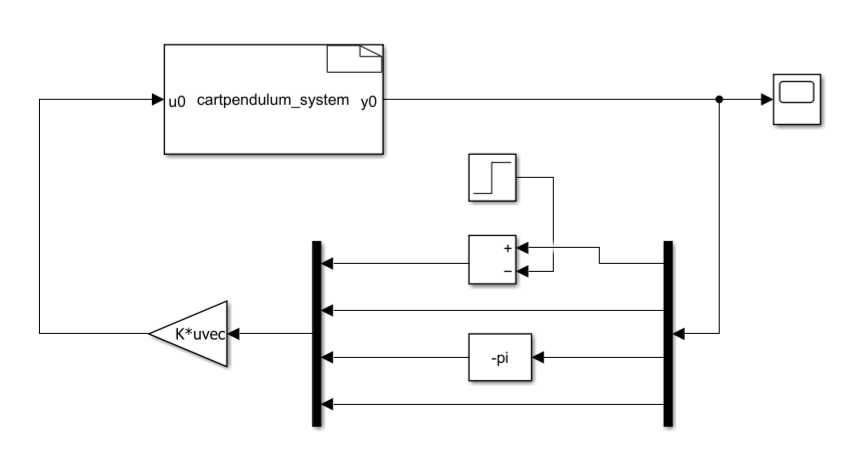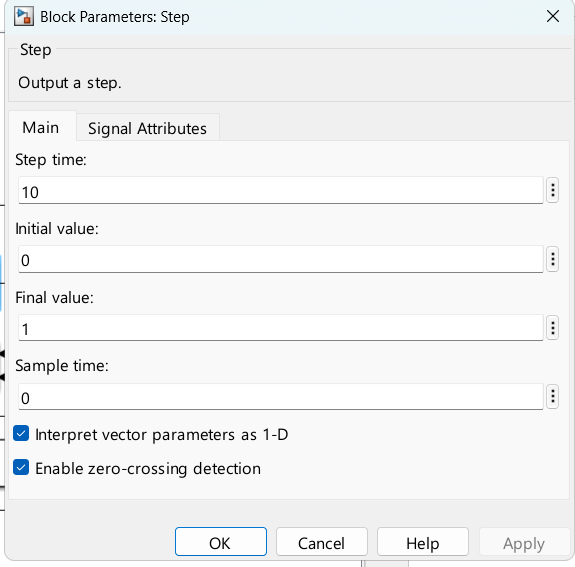

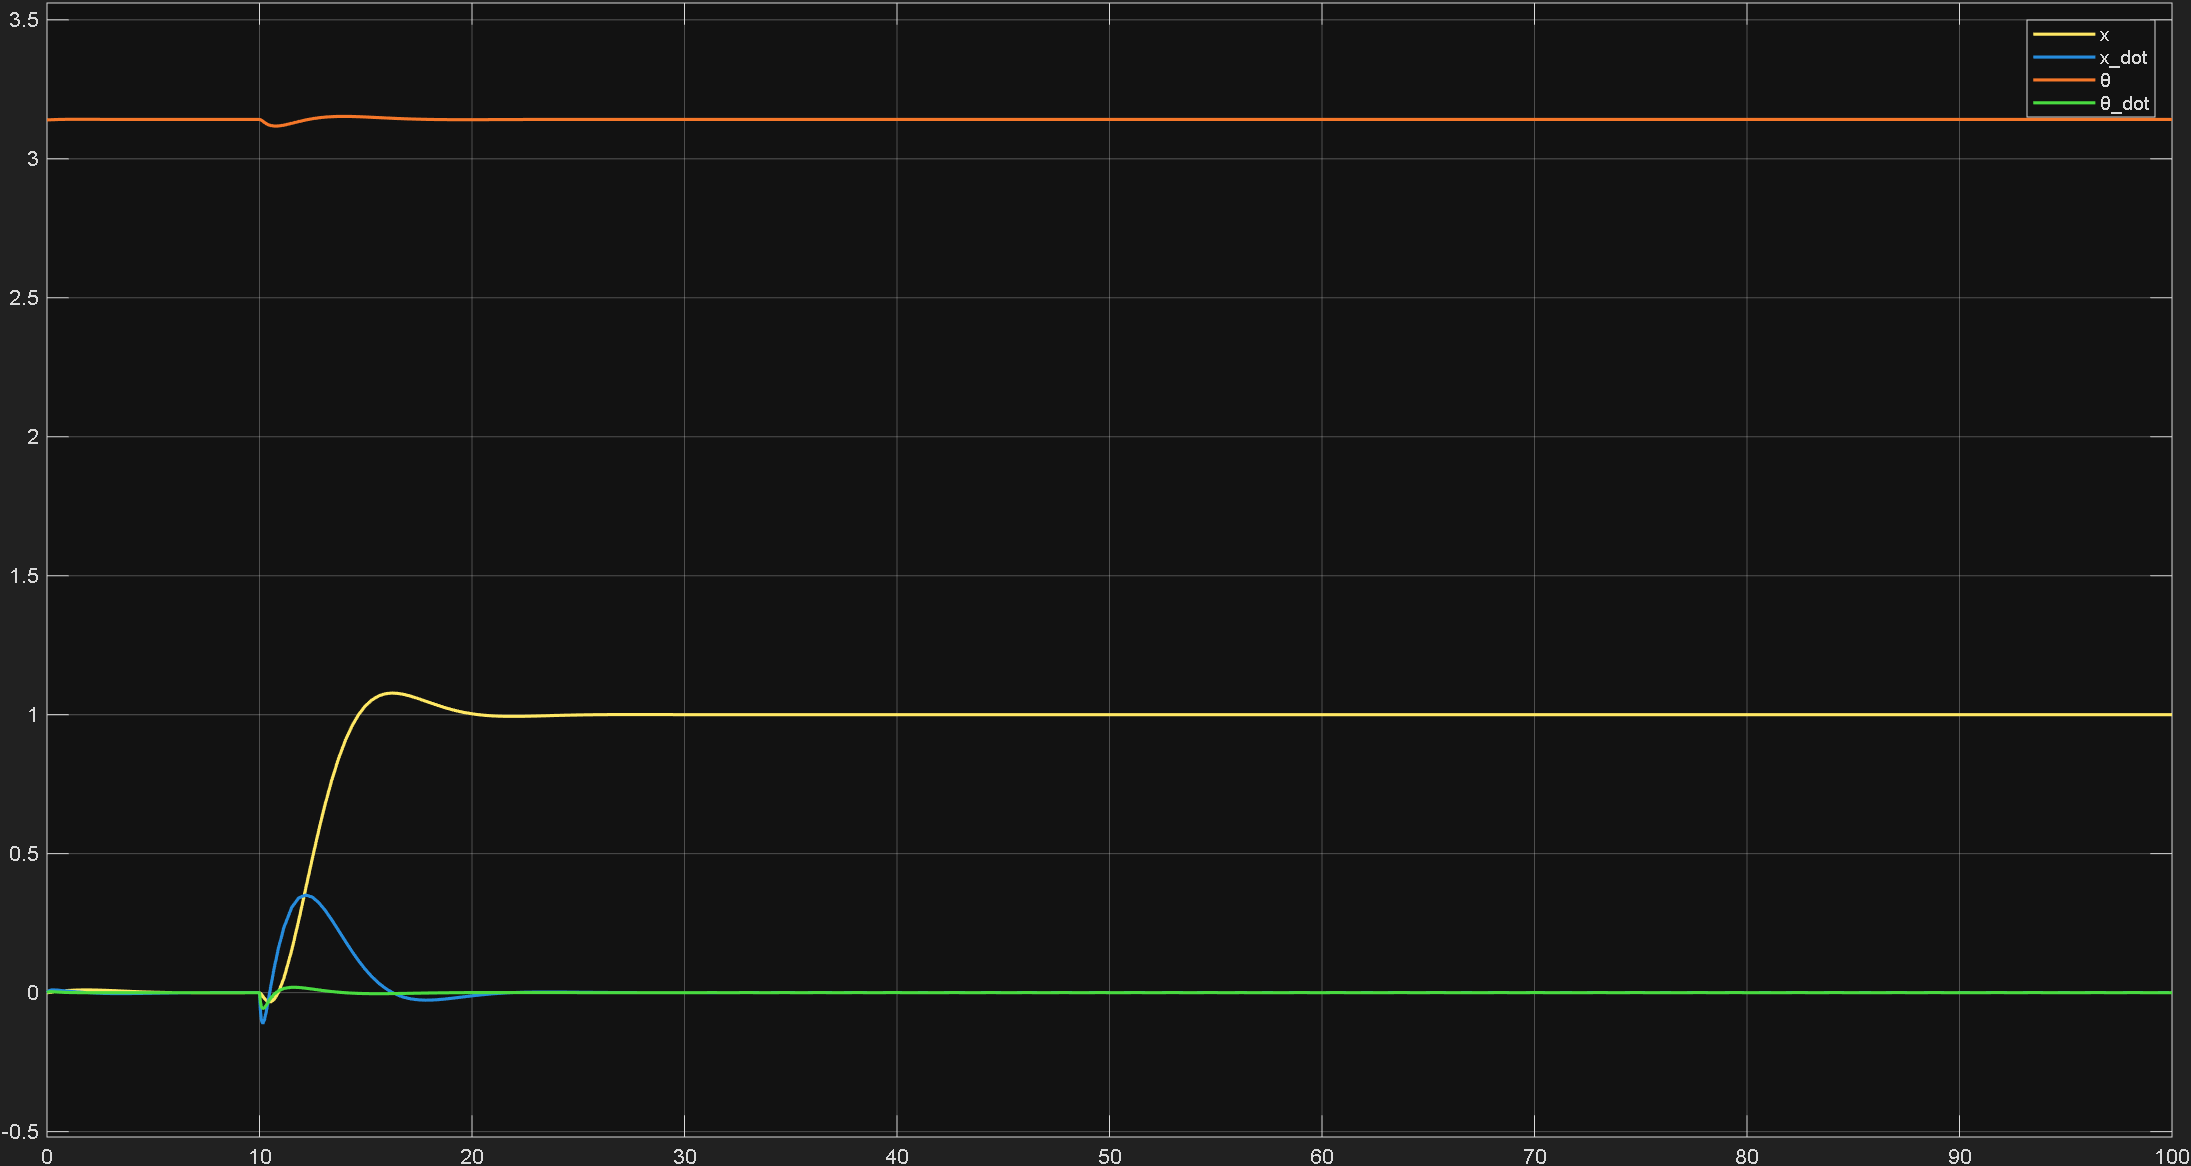

We can graph the system and look at the scope to see the response. Orange represents the angle, yellow is x, blue is x_dot, and green is theta_dot. 

At t=10 we can see that the system moves and goes to 1, the x_dot measurement follows by rising and then falling. We can see the same pattern in theta and theta_dot as there are both a small dip when the system begins to move and eventually stabilizes.

## Building Simulink Block Diagram for LQG

When we cannot measure the state of every variable in the system as sensors can be expensive when scaling, predictive measurement is require using the governing physical equations and estimations. LQG is the combination of a Linear Quadratic Estimator (Kalman Filter in this case) being fed into a Linear Quadratic Regulator (LQR) to stabilize systems. Our system is modeled very similar to the LQR example, however, it will only take measurements of the carts positions and estimate the carts velocity, angle of pendulum and angular velocity to stabilize the system. 

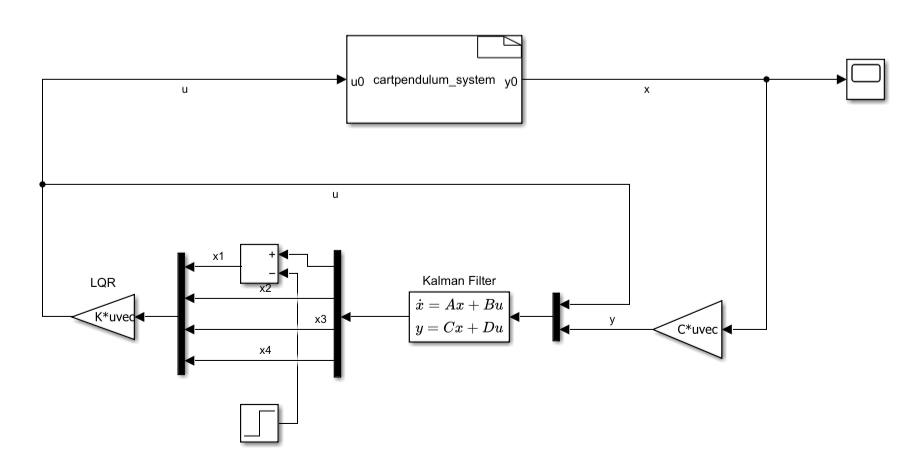

The S-function block is the same as the previous example and represents the systems dynamics for the inverse pendulum problem. We can look into the C block to represent the only measurement.

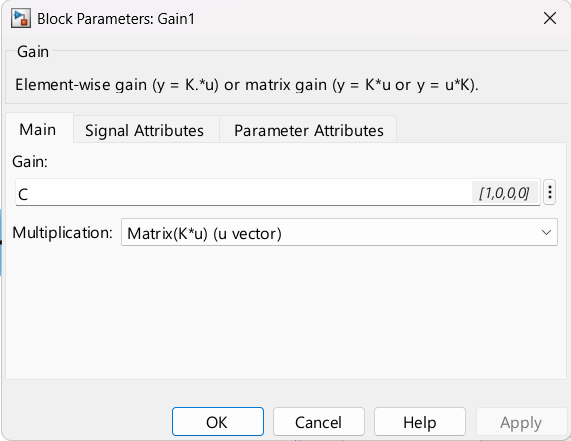

Previously, we answered if the system is observable and for C = [1 0 0 0] (only carts position) we can back out all the rest of  the measurements knowing the governing dynamics. So in this case, we are only using cart position.

Kalman Filter Block

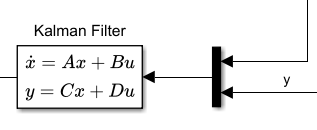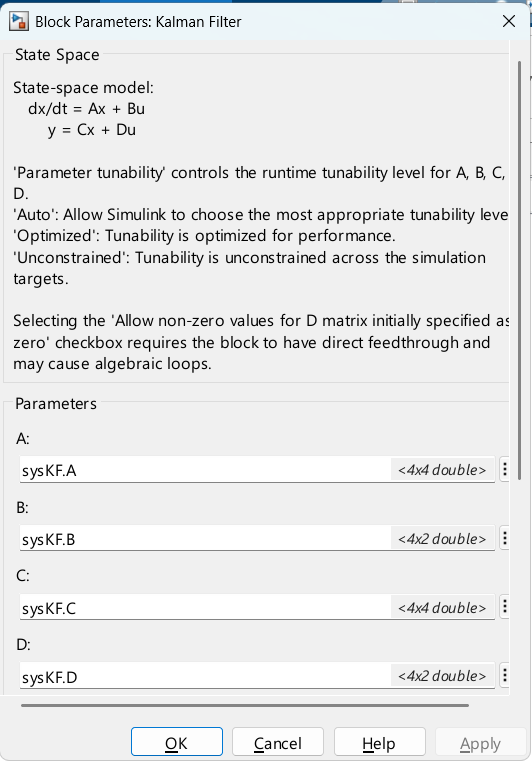

We derived the Kalman Filter in the previous example using: 

Kf = (lqr(A',C',Vd,Vn))';

sysKF = ss(A-Kf*C, [B Kf], eye(4), 0*[B Kf]); 

We considered both noise and disturbances to create and accurate model.

The Kalman Filter block on simulink comprises of the calculated representation from the MATLAB code. The Kalman filter takes in the measurement input y, as well as output values from the LQR to make the best state estimates of the missing unmeasured variables.

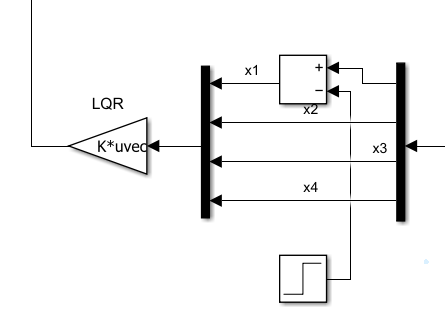

We have estimates of the remaining states. x1->x4. We will be adding the command that at t=10, move the cart to 1m position. This is fed into the same LQR system that was designed seperately. We can see the seperation principle in action as we designed K independently of Kf and still are allowed to combine them to get a stable system.

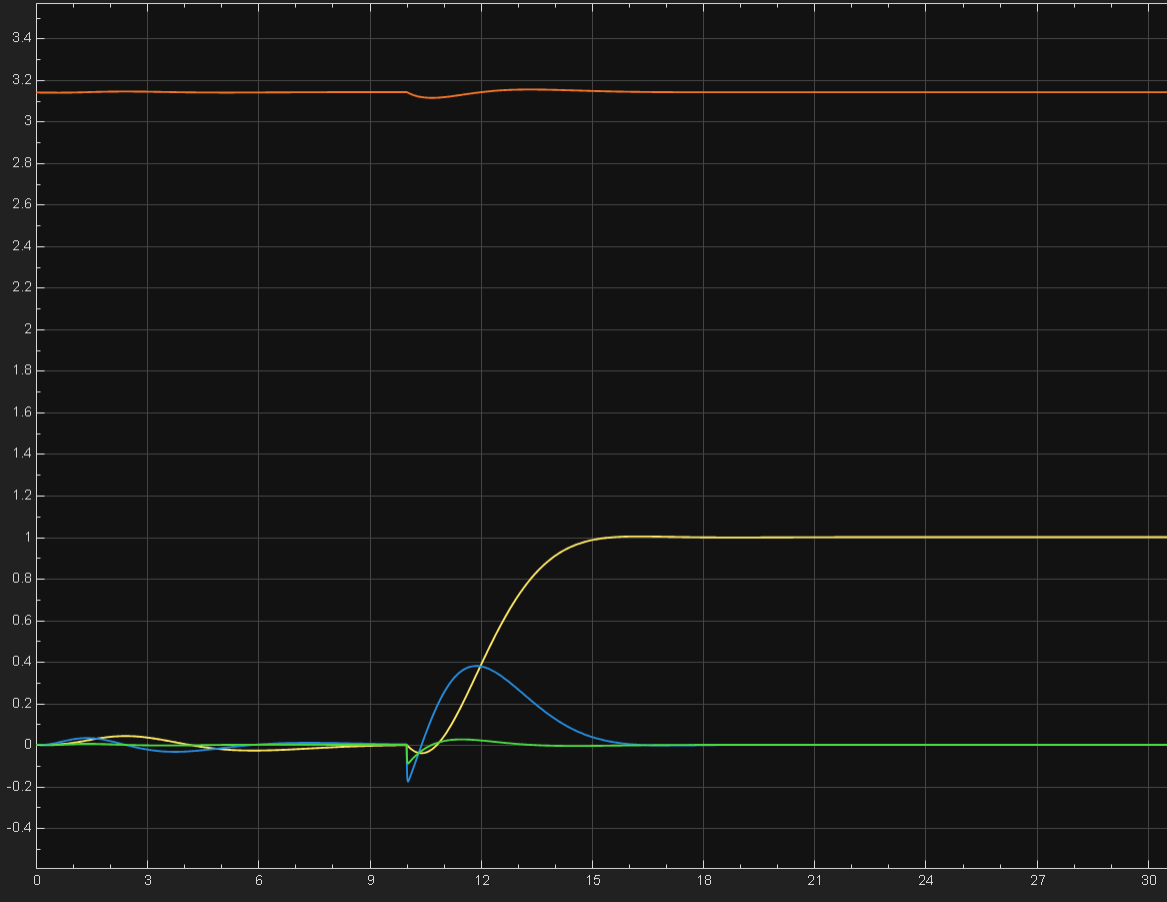

We can see, we are getting the same results as if we were measuring all the variables similar to the LQR. We kick the system, it responds and we can estimate the response given our estimator and the system being an observable one.